filename = "testing1D.mat";
hasMatFile = isfile(filename);
if (hasMatFile)
    load(filename);
end

### Original signal

Combination of 3 frequency

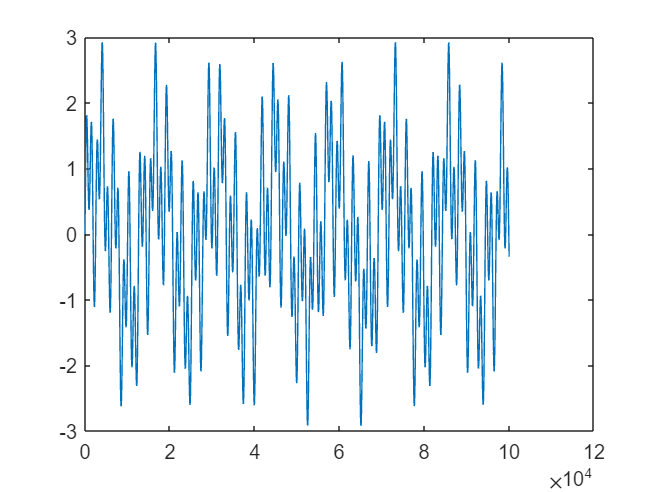

if (~hasMatFile)
    fs = 100;
    t = 0:1/fs:1000;
    f=[2,5,22];
    signal = zeros(1,length(t));
    for fi=f
        signal = signal+sin(t/fi);
    end
end
figure('Name','Clear signal');
plot(signal)

### Raw signal

Add noise to signal

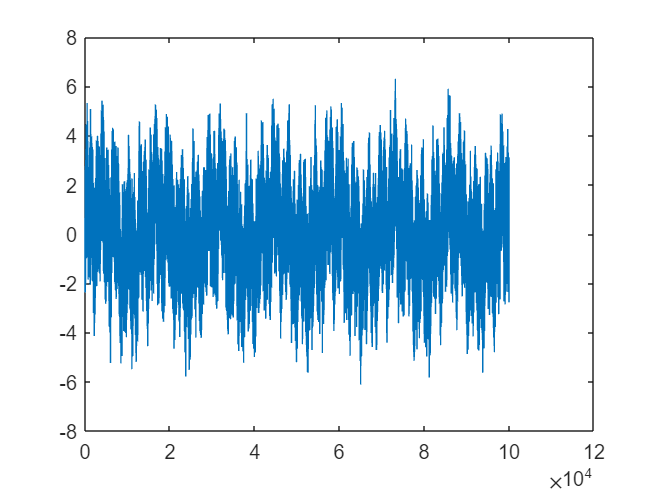

if (~hasMatFile)
    noise = wgn(1,length(t),0);
    raw = signal+noise;
end
figure('Name','Raw signal');
plot(raw);

% psnr
psnr_v = zeros(4,2);
[peaksnr,snr] = psnr(raw, signal);
psnr_v(1,:) = [peaksnr,snr];

### Seperate 5 IMF

if (~hasMatFile)
    % parameters:
    alpha = 5000;       % bandwidth constraint
    tau = 0.25;         % Lagrangian multipliers dual ascent time step
    K = 6;              % number of modes
    DC = 1;             % includes DC part (first mode at DC)
    
    init = 1;           % initialize omegas randomly, may need multiple runs!
    
    tol = K*10^-6;      % tolerance (for convergence)
    
    [u, u_hat, omega]=VMD(raw, alpha, tau, K, DC, init, tol);
end

G = 2; % get G IMR out of K
recontruct = sum(u(1:G,:));
[peaksnr,snr] = psnr(recontruct, signal);
psnr_v(3,:) = [peaksnr,snr];

### Filter noisy signal

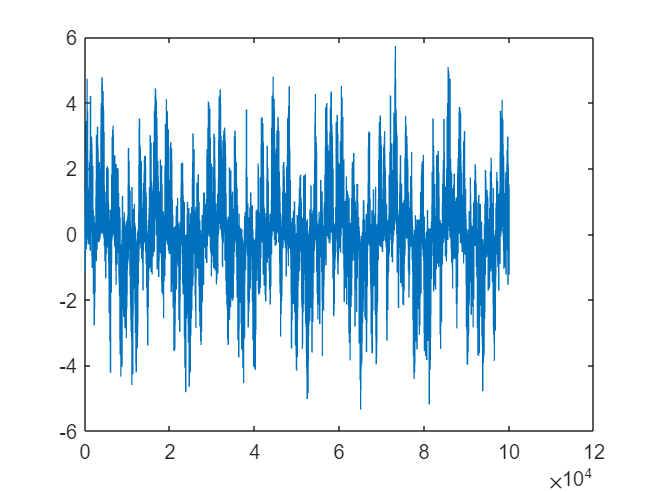

filterType="wiener";
filtered_signal =getFiltered(raw,filterType);
figure('Name','filtered signal');
plot(filtered_signal);

[peaksnr,snr] = psnr(filtered_signal, signal);
psnr_v(2,:) = [peaksnr,snr];

### Residual calculate + filter

residual = raw - recontruct;
filtered_residual = getFiltered(residual,filterType);
removednoise = filtered_residual+recontruct;
[peaksnr,snr] = psnr(removednoise, signal);
psnr_v(4,:) = [peaksnr,snr];

### Plot PSNR

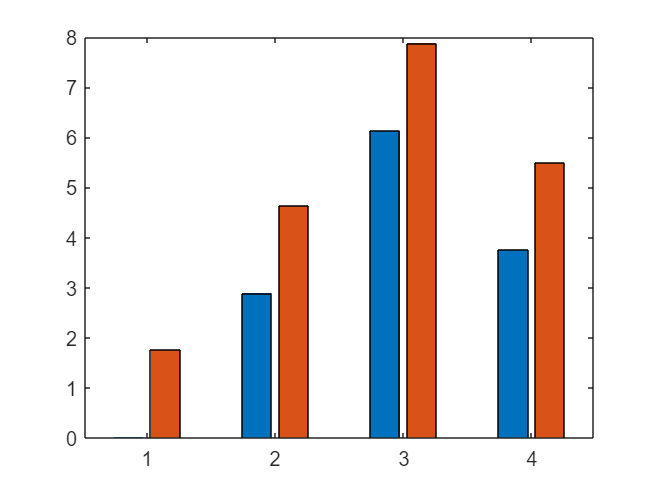

bar(psnr_v);

disp(psnr_v(:,1))

    0.0179
    2.8915
    6.1359
    3.7523



function filtered_signal=getFiltered(raw,filterType)
    filtered_signal =[];
    switch filterType
        case "wiener"
            filtered_signal = wiener2(raw);
        case "median"
            filtered_signal = medfilt1(raw);
        case "mean"
            windowSize = 5; 
            b = (1/windowSize)*ones(1,windowSize);
            a = 1;
            filtered_signal = filter(b,a,raw);
    end
end
